## **Progetto del corso di Controllo Avanzato Multivariabile**

#### Progettazione di un MPC per il controllo di un 

#### Continuous-flow Stirred-Tank Reactor (CSTR)

Wasim Essbai, Matteo Verzeroli

Prof. Antonio Ferramosca

Dott. Marco Polver

## 0. Setup

clear;
clc;
close all
set(0,'DefaultLineLineWidth', 1.5);
set(0,'defaultAxesFontSize', 14)
%set(0,'DefaultFigureWindowStyle', 'docked') 
set(0,'DefaultFigureWindowStyle', 'normal')
set(0,'defaulttextInterpreter','latex')
rng('default');
%load('ws')

## 1. Parametri del reattore

q0 = 10;
V = 150;
k0 = 7.2*10^(10);
ER = 8750;
dHr = -50000;
UA = 50000;
ro = 1000;
Cp = 0.239;
tau_c = 1.5;
CAf = 1;
Tf = 370;
save('ws')

## 2. Equazioni di stato


$$\dot C_A(t) = \frac {q_o} V \cdot (C_{Af}-C_A(t))-k_0 \cdot exp(- \frac E {R\cdot T(t)})\cdot C_A(t)$$



$$\dot T(t) = \frac {q_o} V \cdot (T_{f}-T(t))+\frac {(-\Delta H_r)\cdot k_0} {\rho \cdot C_p} \cdot exp(- \frac E {R\cdot T(t)})\cdot C_A(t) + \frac {UA} {V\cdot \rho \cdot C_p} \cdot (T_c(t)-T(t))$$



$$\dot T_c(t) =\frac {T_r(t) - T_c(t)} {\tau_c}$$


## 3a. Linearazzazione del sistema

% Stato di equilibrio
Ca_eq = 0.5054;
T_eq = 315.5491;
Tc_eq = 308;

% Ingresso di equilibrio
Tr_eq = 308;

% Matrici del sistema tangente

A_c = [-k0*exp(-ER/T_eq) - q0/V, -Ca_eq*ER*k0*exp(-ER/T_eq)/(T_eq^2), 0;
      ((-dHr)*k0/(ro*Cp))*exp(-ER/T_eq), -q0/V + Ca_eq*((-dHr)*k0/(ro*Cp))*exp(-ER/T_eq)*ER/(T_eq^2) - UA/(V*ro*Cp), UA/(V*ro*Cp);
      0, 0, -1/tau_c];
B_c = [0;0;1/tau_c];
C_c = [1, 0, 0]; % si assume Ca come uscita del sistema
D_c = 0;

continuous_time_ss = ss(A_c,B_c,C_c,D_c);
save('ws')

## 3b. Discretizzazione del sistema linearizzato

Ts = 2; % tempo di campionamento

discrete_time_ss = c2d(continuous_time_ss, Ts);

A = discrete_time_ss.A;
B = discrete_time_ss.B;
C = discrete_time_ss.C;
D = discrete_time_ss.D;

% Matrice di raggiungibilità
Mr = ctrb(discrete_time_ss);
Mr_rank = rank(Mr);

% Autovalori del sistema
lambda0 = eig(A);
save('ws')

## 4. Vincoli sul sistema linearizzato

% Vincoli sullo stato
Hx = [1,0,0;
      -1,0,0;
      0,1,0;
      0,-1,0;
      0,0,1;
      0,0,-1];
hx = [0.954 - Ca_eq; -0.38 + Ca_eq; 10^6; 10^6; 10^6; 10^6];

% Vincoli sull'ingresso
Hu = [1;-1];
hu = [310 - Tr_eq; -280 + Tr_eq];
save('ws')

## 5. Invariant set per il sistema controllato

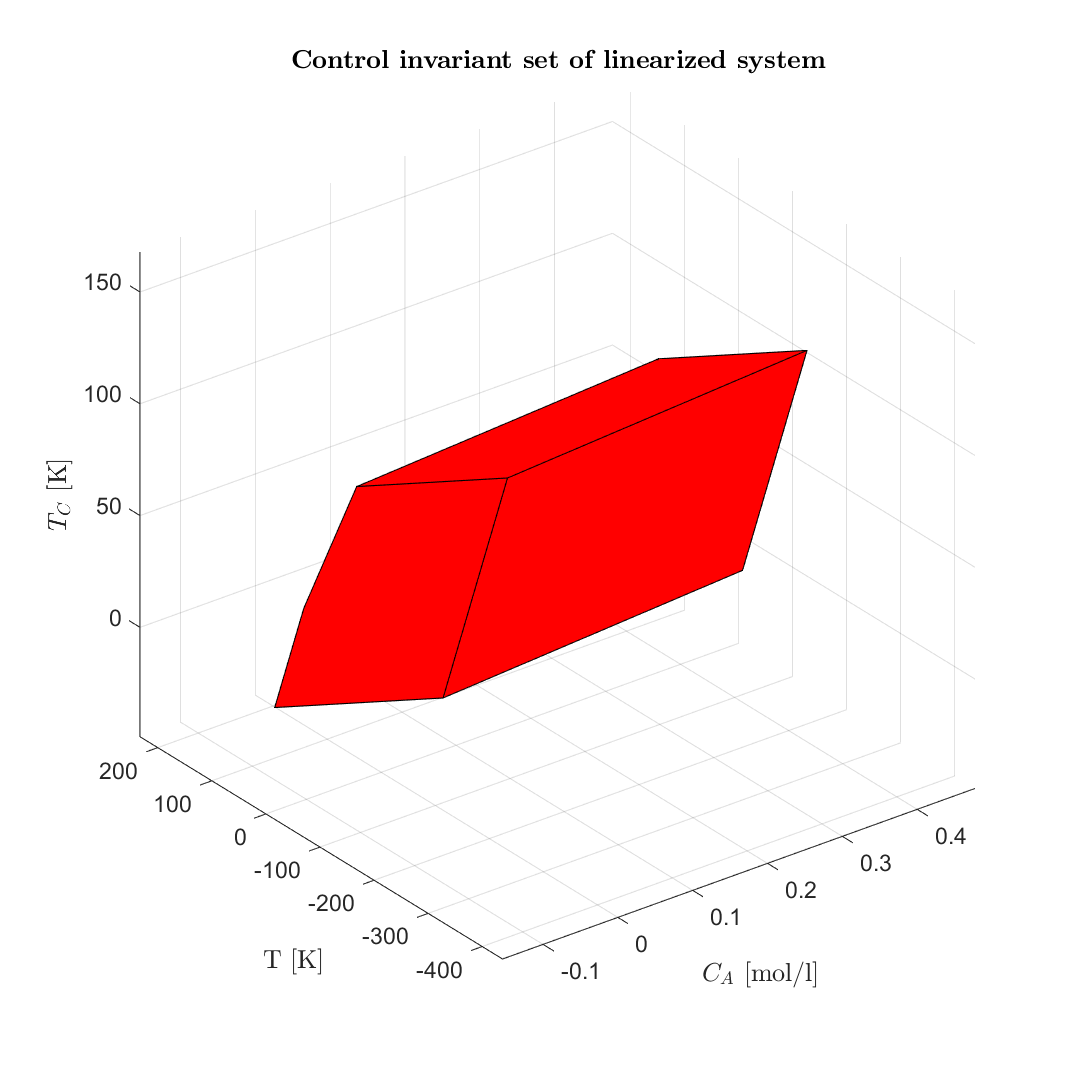

% Matrici del costo quadratico
Q = eye(3);
%Q = 10000*eye(3);
%R = 10000;
R = 1;

%   Computazione control invariant set
[CIS_H,CIS_h] = cis(A,B,[0; 0; 0],0,Hx,hx,Hu,hu,Q,R);

CIS = Polyhedron(CIS_H,CIS_h);

figure('Position', [0 0 1000 1000])
CIS.plot('linewidth',0.5);
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');

%exportgraphics(gcf,'CIS.png','Resolution',400);
save('ws')

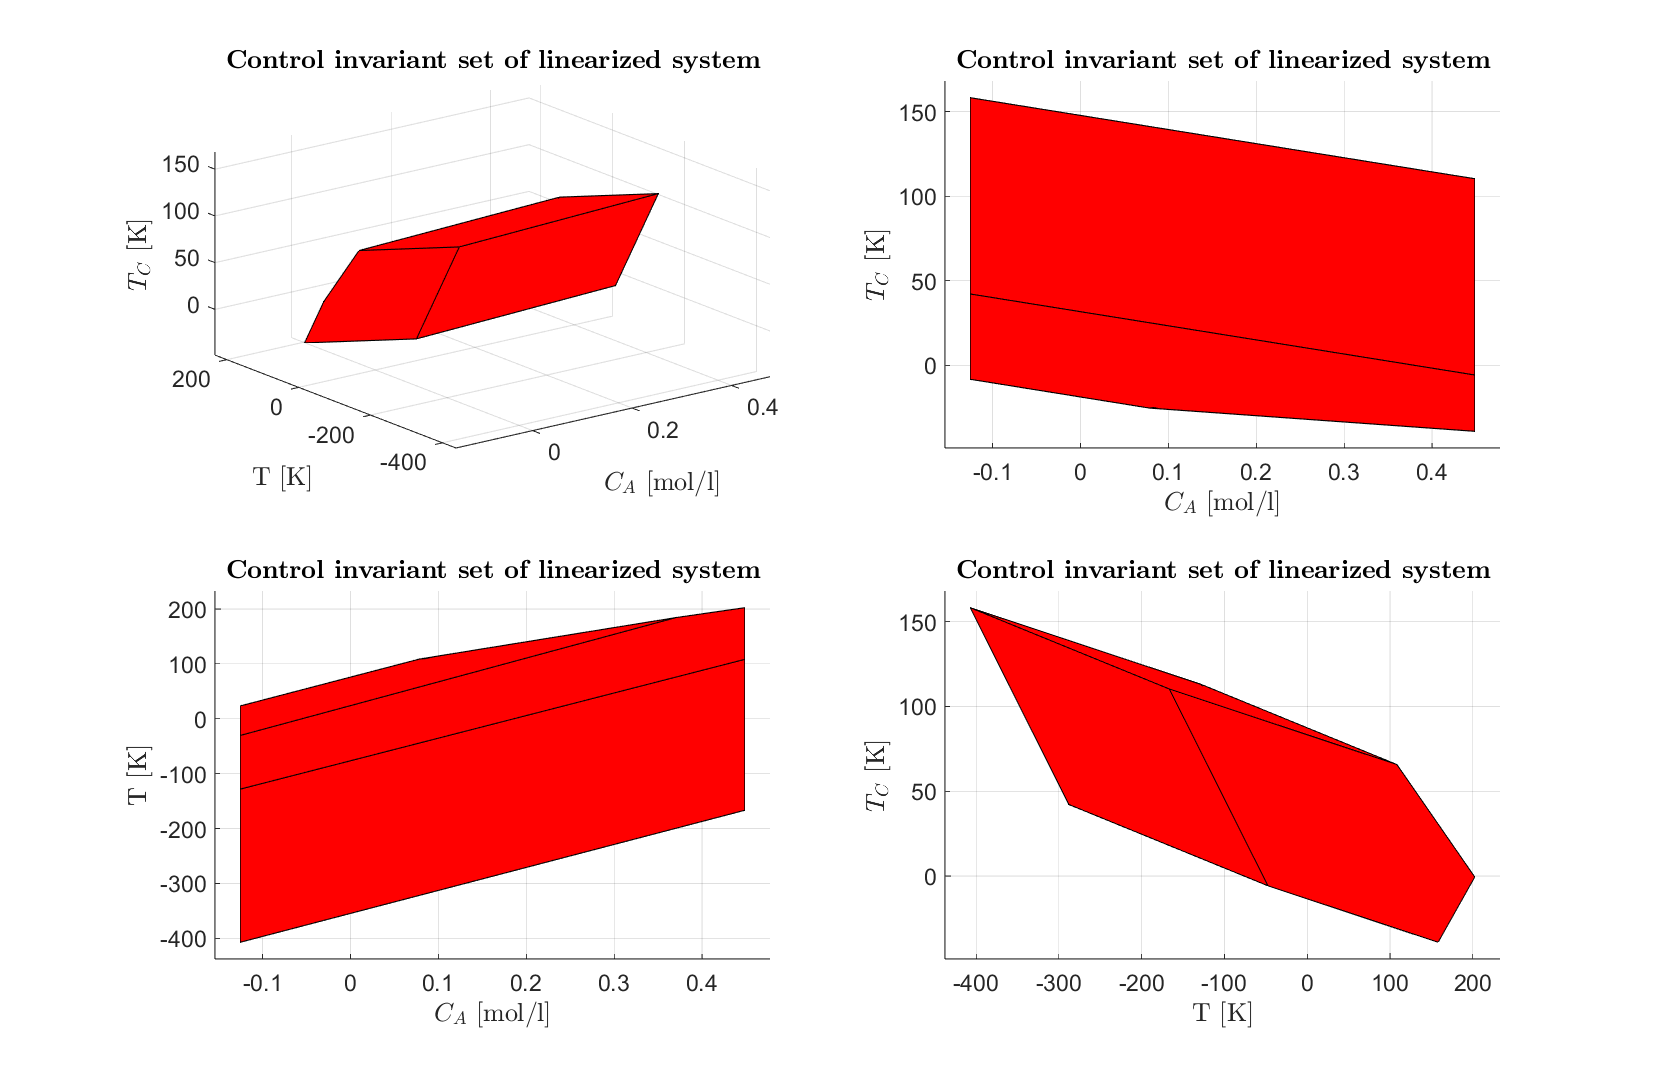

figure('Position', [0 0 2000 1300])
subplot(2,2,1);
CIS.plot('linewidth',0.5);
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');

subplot(2,2,2);
CIS.plot('linewidth',0.01);
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([0 0])

subplot(2,2,3);
CIS.plot('linewidth',0.01);
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([0 90])

subplot(2,2,4);
CIS.plot('linewidth',0.01);
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([90 0])

%exportgraphics(gcf,'CIS-views.png','Resolution',400);
save('ws')

## 6. N-step-controllable set dell'invariant set

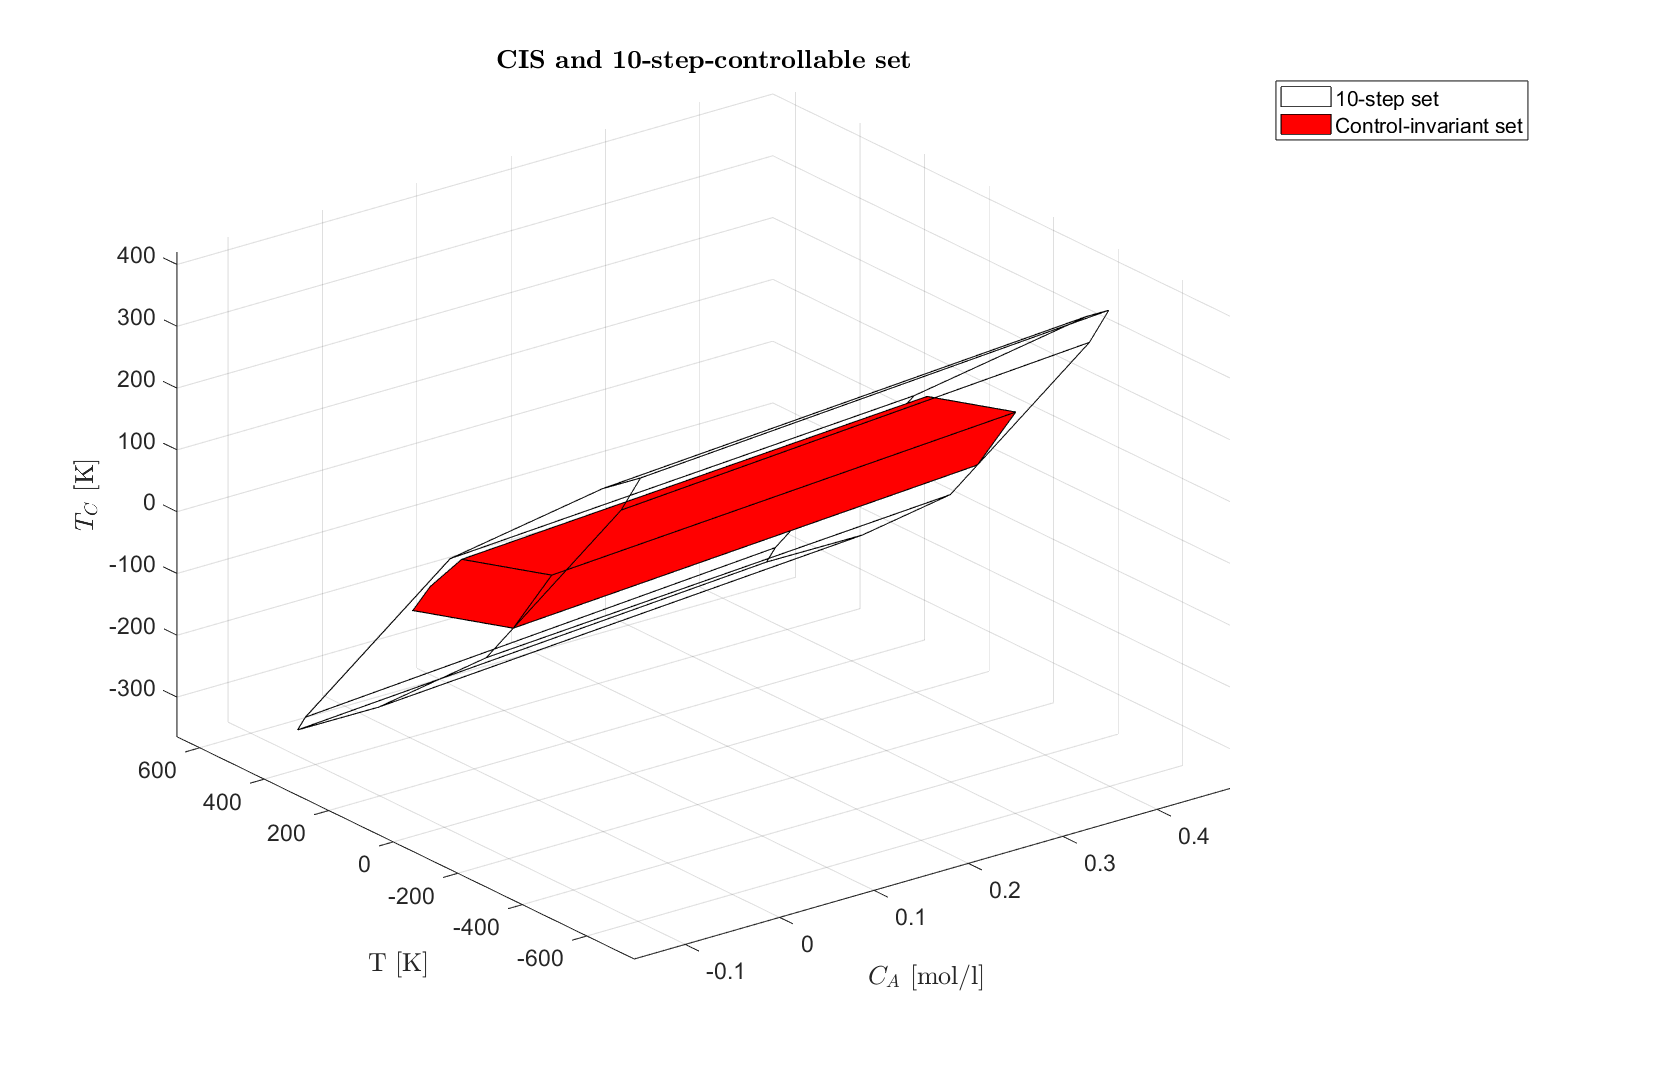

%   Orizzonte di predizione
N = 10;

[Np_steps_H, Np_steps_h] = controllable_set(Hx,hx,Hu,hu,CIS_H,CIS_h,A,B,N);
Np_step_set = Polyhedron('A',Np_steps_H,'b',Np_steps_h);

%Np_step_set.contains(x_log(:,1) - x_ref)

figure('Position', [0 0 2000 1300])
Np_step_set.plot('Alpha',0,'linewidth',0.5);
title("\textbf{CIS and " + int2str(N) + "-step-controllable set}");
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot('linewidth',0.1)
legend({int2str(N) + "-step set", 'Control-invariant set'});

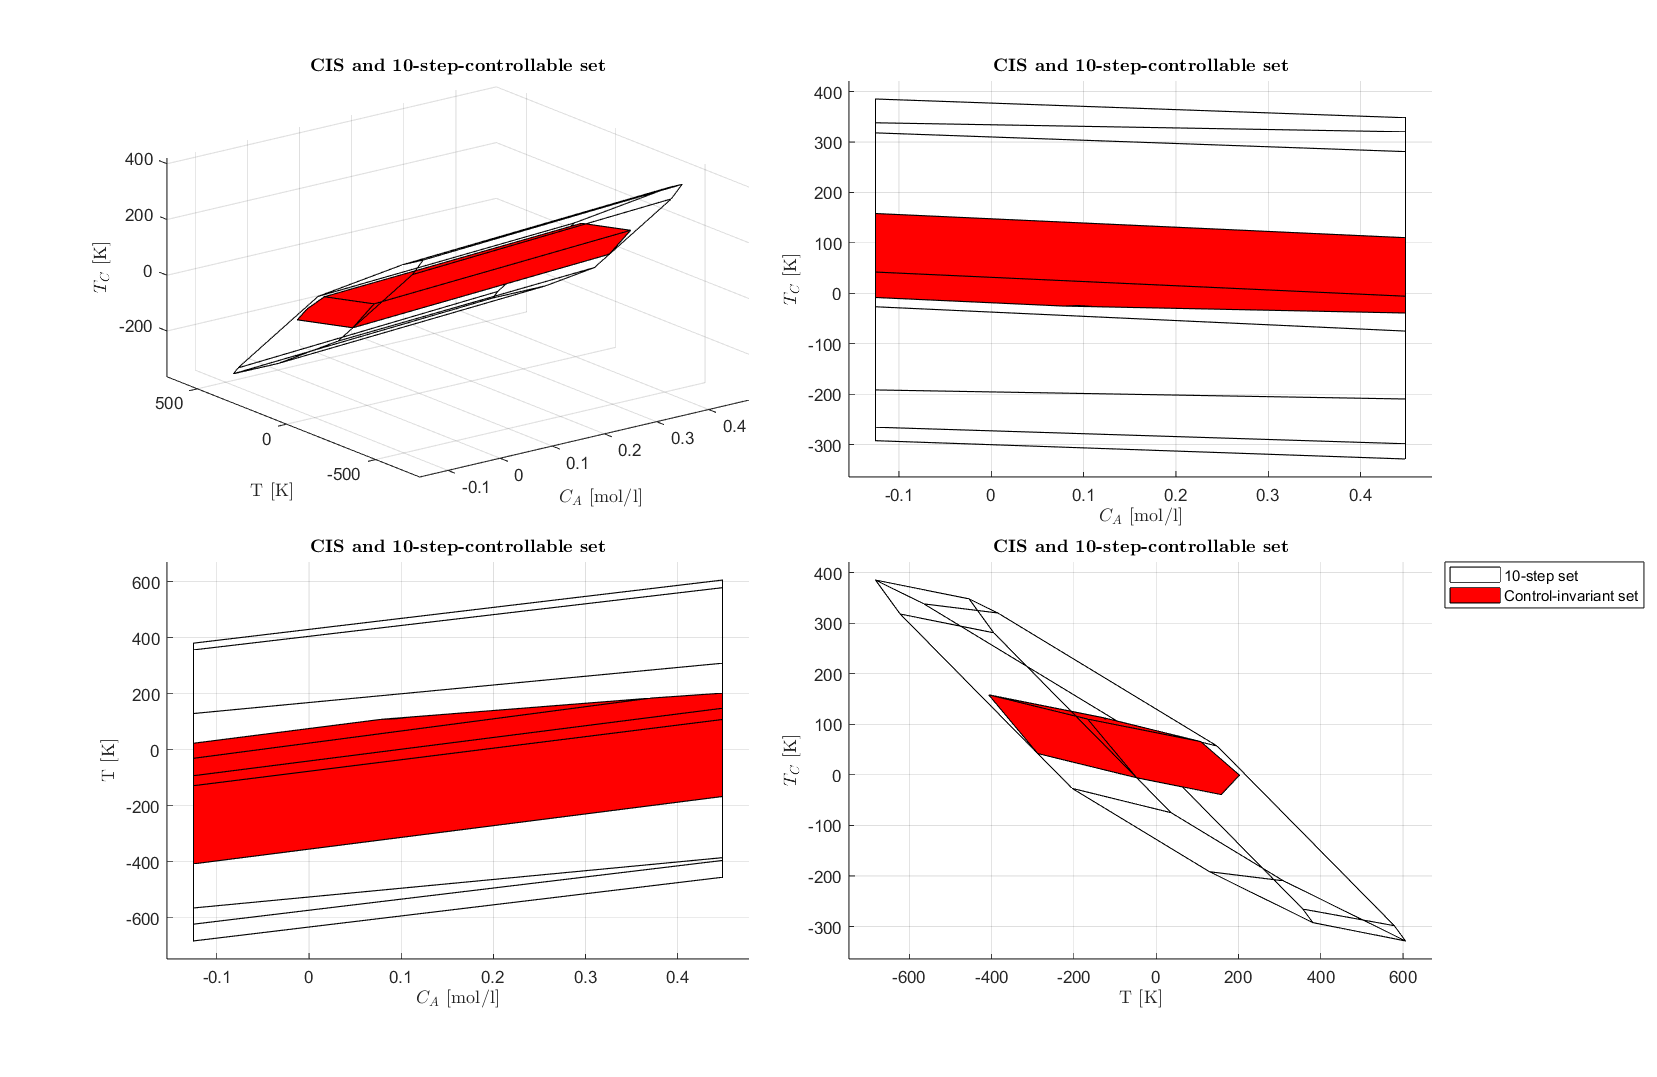


%exportgraphics(gcf,'CIS-N-step-CS.png','Resolution',400);
figure('Position', [0 0 2000 1300])

tiledlayout('flow','TileSpacing','compact');
nexttile

Np_step_set.plot('Alpha',0,'linewidth',0.5);
title("\textbf{CIS and " + int2str(N) + "-step-controllable set}");
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot('linewidth',0.1)

nexttile
Np_step_set.plot('Alpha',0,'linewidth',0.4);
title("\textbf{CIS and " + int2str(N) + "-step-controllable set}");
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot('linewidth',0.01)
view([0 0])

nexttile
Np_step_set.plot('Alpha',0,'linewidth',0.4);
title("\textbf{CIS and " + int2str(N) + "-step-controllable set}");
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot('linewidth',0.01)
view([0 90])

nexttile
Np_step_set.plot('Alpha',0,'linewidth',0.4);
title("\textbf{CIS and " + int2str(N) + "-step-controllable set}");
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot('linewidth',0.01) 
view([90 0])

leg = legend({int2str(N) + "-step set", 'Control-invariant set'});

leg.Location(1);

%exportgraphics(gcf,'CIS-N-step-CS-views.png','Resolution',400);
save('ws')

## 6. Design MPC e simulazione

%   Numero di step simulati
T_sim = 60;

%   Riferimento
x_ref = [Ca_eq; T_eq; Tc_eq];
u_ref = Tr_eq;

x_ref_lin = [0; 0; 0];
u_ref_lin = 0;

mpc = mpc_ingredients(A,B,Hx,hx,Hu,hu,CIS_H,CIS_h,x_ref_lin,u_ref_lin,Q,R,N);

%   Log stati e ingresso sistema
x_log = zeros(3,T_sim+1);
u_log = zeros(1,T_sim);
flags = zeros(1,T_sim);

x_log(:,1) = [0.853; 296.986; 292]; % condizione iniziale
%x_log(:,1) = [0.853; 270; 280]; Non dovrebbe funzionare con N<=3

if Np_step_set.contains(x_log(:,1) - x_ref)
    for tt = 1:T_sim
    
        %   Stato sistema linearizzato
        x_lin = x_log(:,tt) - [Ca_eq; T_eq; Tr_eq];
        x_lin_shifted = x_lin - x_ref_lin;
    
        %   Impostazioni MPC relative alla condizione iniziale
        f = mpc.f_base * x_lin_shifted;
        b_ineq = mpc.b_ineq_base - mpc.b_ineq_x0_factor * x_lin_shifted;
        
        %   Risoluzione problema di ottimizzazione
        options = optimset('Display', 'off');
        warning('off','all')
        [delta_u_seq,~,exitflag] = quadprog(mpc.F,f,mpc.A_ineq,b_ineq,[],[],[],[],[],options);
        warning('on','all')
        
        flags(tt) = exitflag;
    
        %   Risposta del sistema
        u_log(tt) = u_ref + delta_u_seq(1);
        
        dxdt = @(t,x) cstr(t,x,u_log(tt),q0,V, k0, ER, dHr, UA, ro, Cp, tau_c, CAf, Tf);
        [~,xx] = ode45(dxdt,[0 Ts],x_log(:,tt));
        x_log(:,tt+1) = xx(end,:)';
    end
else
    disp("Condizione iniziale non ammissibile")
end
if sum(flags ~= 1)
    disp('Qualche errore')
end
save('ws')  

## 8. Plot dei risultati

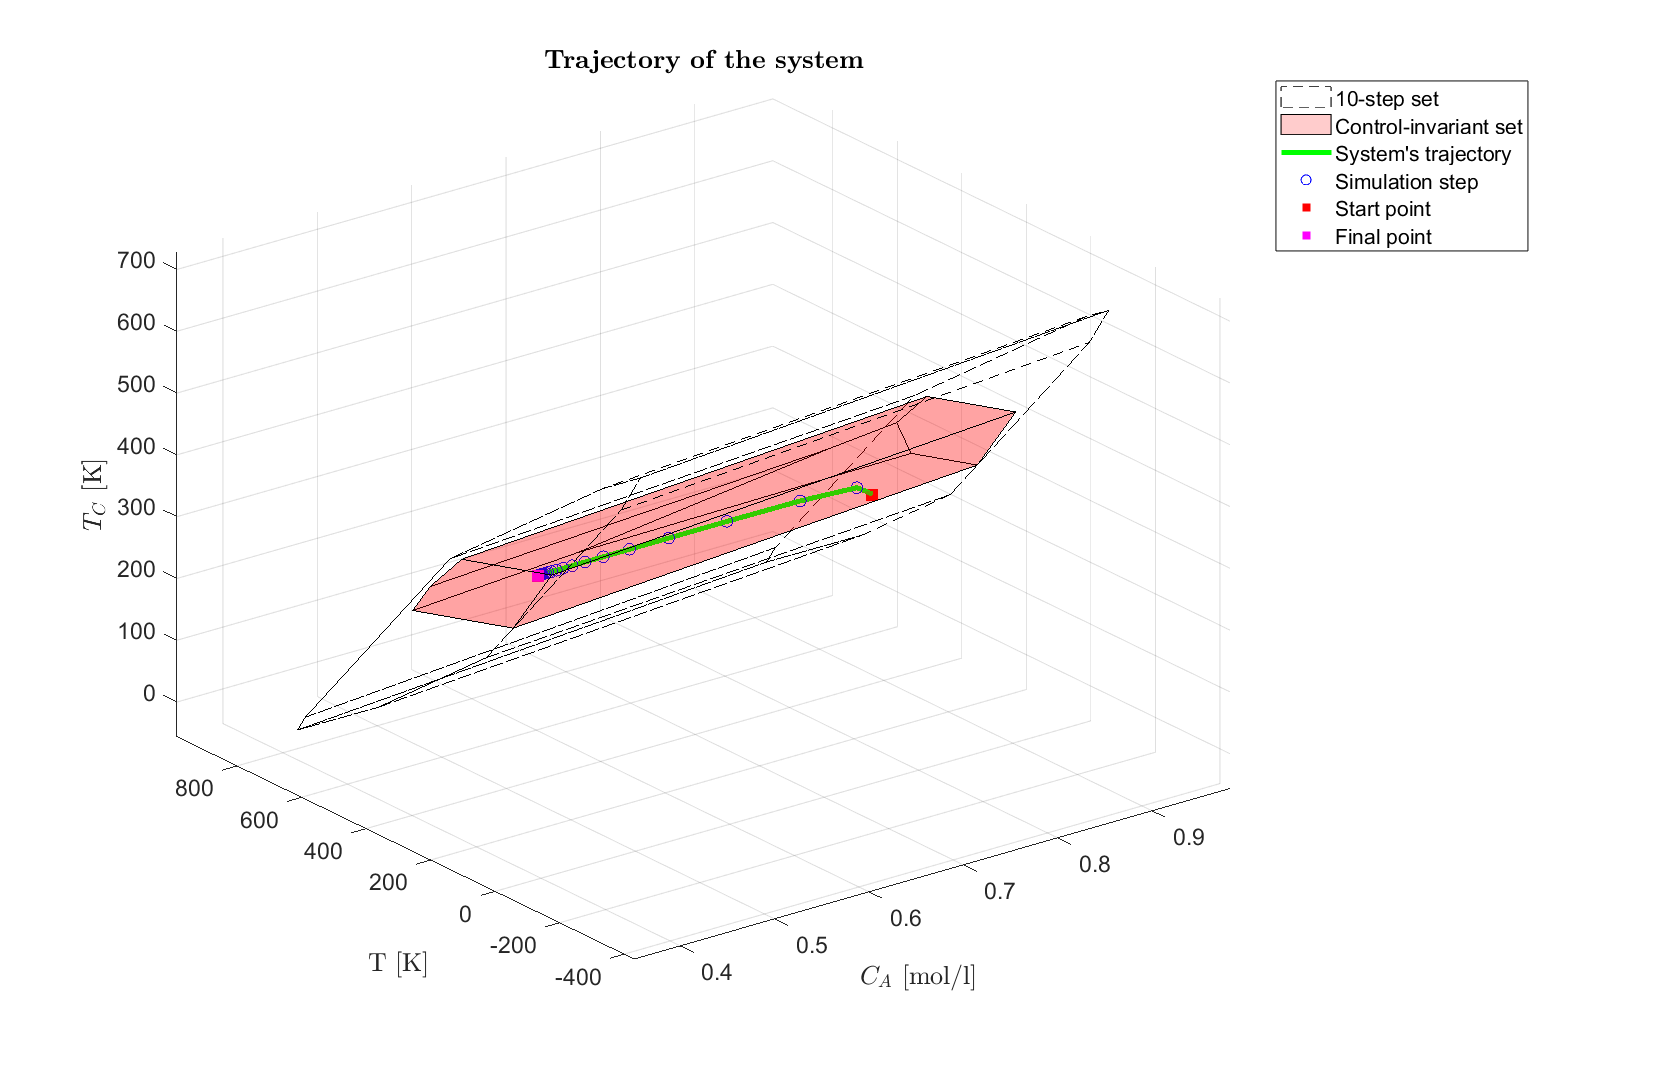

%   Traslazione del CIS e dell'N-step set nelle coordinate originali
CIS_shifted = CIS + x_ref;
Np_step_set_shifted = Np_step_set + x_ref;

figure('Position', [0 0 2000 1300])
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.1);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.2,'linewidth', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,2:end-1),x_log(2,2:end-1), x_log(3,2:end-1), 50,'blue');
scatter3(x_log(1,1),x_log(2,1), x_log(3,1), 80,'red','filled','square');
scatter3(x_log(1,end),x_log(2,end), x_log(3,end), 80,'magenta','filled','square');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
legend({int2str(N) + "-step set", 'Control-invariant set', 'System''s trajectory', 'Simulation step', 'Start point', 'Final point'});
exportgraphics(gcf,'MPC.png','Resolution',400);

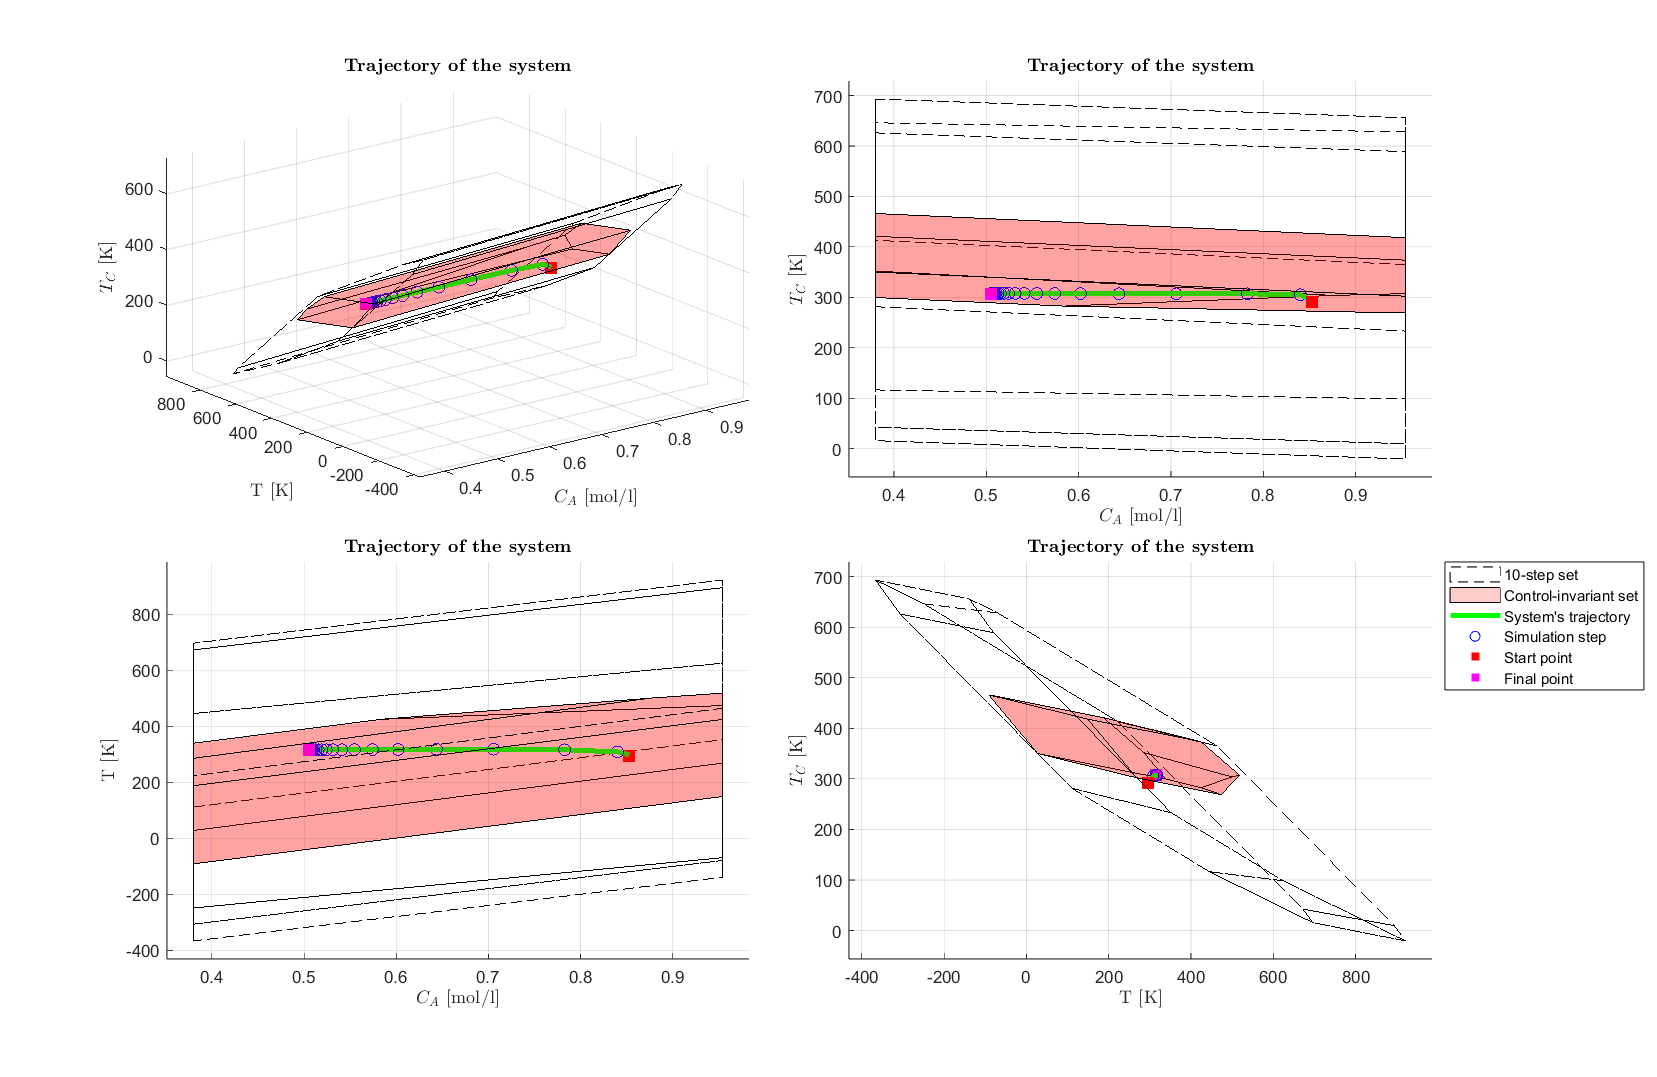

figure('Position', [0 0 2000 1300])

tiledlayout('flow','TileSpacing','compact');
nexttile

Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.1);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.2,'linewidth', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,2:end-1),x_log(2,2:end-1), x_log(3,2:end-1), 50,'blue');
scatter3(x_log(1,1),x_log(2,1), x_log(3,1), 80,'red','filled','square');
scatter3(x_log(1,end),x_log(2,end), x_log(3,end), 80,'magenta','filled','square');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');

nexttile
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.1);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.2,'linewidth', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,2:end-1),x_log(2,2:end-1), x_log(3,2:end-1), 50,'blue');
scatter3(x_log(1,1),x_log(2,1), x_log(3,1), 80,'red','filled','square');
scatter3(x_log(1,end),x_log(2,end), x_log(3,end), 80,'magenta','filled','square');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([0 0])

nexttile
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.1);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.2,'linewidth', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,2:end-1),x_log(2,2:end-1), x_log(3,2:end-1), 50,'blue');
scatter3(x_log(1,1),x_log(2,1), x_log(3,1), 80,'red','filled','square');
scatter3(x_log(1,end),x_log(2,end), x_log(3,end), 80,'magenta','filled','square');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([0 90])

nexttile
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.1);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.2,'linewidth', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,2:end-1),x_log(2,2:end-1), x_log(3,2:end-1), 50,'blue');
scatter3(x_log(1,1),x_log(2,1), x_log(3,1), 80,'red','filled','square');
scatter3(x_log(1,end),x_log(2,end), x_log(3,end), 80,'magenta','filled','square');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');    
zlabel('$T_C$ [K]');
view([90 0])

leg = legend({int2str(N) + "-step set", 'Control-invariant set', 'System''s trajectory', 'Simulation step', 'Start point', 'Final point'});
leg.Location(1);
exportgraphics(gcf,'MPC-view.png','Resolution',400);

## 8.1 Plot degli stati e dell'ingresso

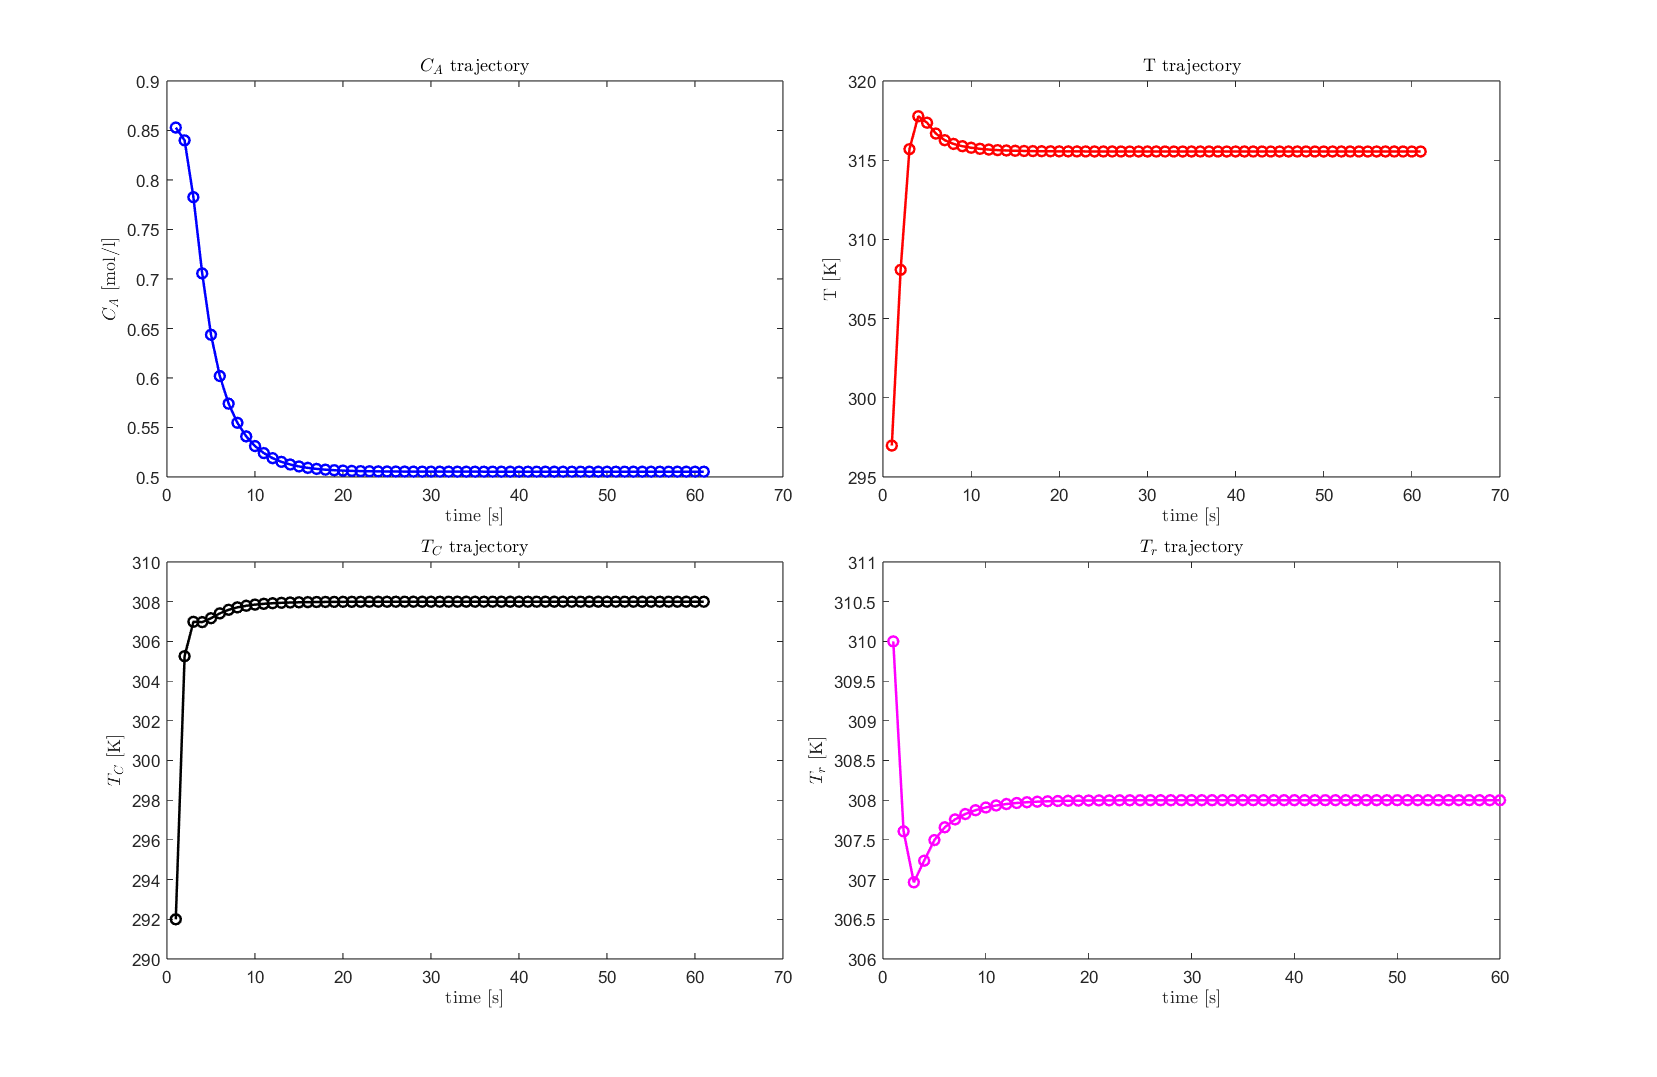

figure('Position', [0 0 2000 1300])

tiledlayout('flow','TileSpacing','compact');
nexttile

plot(x_log(1,:),'-o','Color','blue')
title('$C_A$ trajectory')
xlabel('time [s]');
ylabel('$C_A$ [mol/l]');

nexttile

plot(x_log(2,:),'-o', 'Color', 'red')
title('T trajectory')
xlabel('time [s]');
ylabel('T [K]');

nexttile

plot(x_log(3,:),'-o', 'Color','black')
title('$T_C$ trajectory')
xlabel('time [s]');
ylabel('$T_C$ [K]');
ylim([290 310])

nexttile

plot(u_log(1,:),'-o', 'Color', 'magenta')
title('$T_r$ trajectory')
xlabel('time [s]');
ylabel('$T_r$ [K]');
ylim([306 311])

exportgraphics(gcf,'states-input-1s.png','Resolution',400);